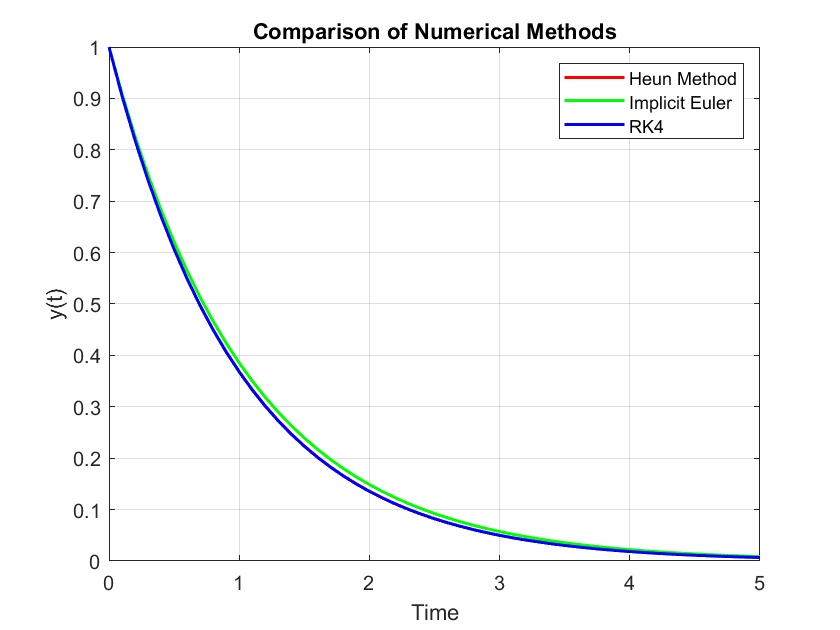

clc;
clear;
close all;

%% ==============================
% 1. DEFINE DIFFERENTIAL EQUATION
% dy/dt = -y
%% ==============================
f = @(t, y) -y;

t0 = 0;
y0 = 1;
h = 0.1;
t_end = 5;

t = t0:h:t_end;

%% ==============================
% 2. HEUN'S METHOD
%% ==============================
y_heun = zeros(size(t));
y_heun(1) = y0;

for i = 1:length(t)-1
    k1 = f(t(i), y_heun(i));
    y_predict = y_heun(i) + h*k1;
    k2 = f(t(i+1), y_predict);
    
    y_heun(i+1) = y_heun(i) + (h/2)*(k1 + k2);
end

%% ==============================
% 3. IMPLICIT EULER METHOD
%% ==============================
y_ie = zeros(size(t));
y_ie(1) = y0;

for i = 1:length(t)-1
    y_guess = y_ie(i);
    
    for j = 1:5  % iteration for convergence
        y_guess = y_ie(i) + h * f(t(i+1), y_guess);
    end
    
    y_ie(i+1) = y_guess;
end

%% ==============================
% 4. RUNGE-KUTTA 4TH ORDER (RK4)
%% ==============================
y_rk4 = zeros(size(t));
y_rk4(1) = y0;

for i = 1:length(t)-1
    k1 = f(t(i), y_rk4(i));
    k2 = f(t(i)+h/2, y_rk4(i)+h*k1/2);
    k3 = f(t(i)+h/2, y_rk4(i)+h*k2/2);
    k4 = f(t(i)+h, y_rk4(i)+h*k3);
    
    y_rk4(i+1) = y_rk4(i) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
end

%% ==============================
% 5. PLOT COMPARISON
%% ==============================
figure;
plot(t, y_heun, 'r', 'LineWidth', 1.5); hold on;
plot(t, y_ie, 'g', 'LineWidth', 1.5);
plot(t, y_rk4, 'b', 'LineWidth', 1.5);

legend('Heun Method', 'Implicit Euler', 'RK4');
xlabel('Time');
ylabel('y(t)');
title('Comparison of Numerical Methods');
grid on;

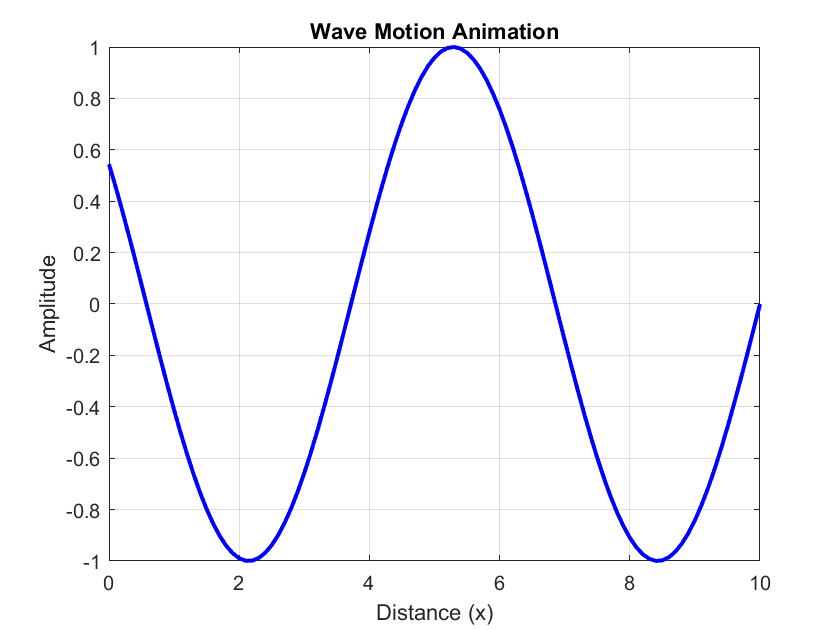


%% ==============================
% 6. WAVE ANIMATION
%% ==============================
x = 0:0.1:10;
c = 1;

figure;

for time = 0:0.1:10
    y = sin(x - c*time);
    
    plot(x, y, 'b', 'LineWidth', 2);
    ylim([-1 1]);
    xlabel('Distance (x)');
    ylabel('Amplitude');
    title('Wave Motion Animation');
    grid on;
    
    pause(0.1);
end